# **Introduction to Cell Designer**

**Note: This tutorial is a draft and needs completion. Contributions welcome!**

**Table of Contents **							

**1  Abstract **				

**2  Introduction**							

**3  Parse a CellDesiger file into Matlab **							

**4  Width and colour attribute modifications **					

**        4.1 Change the thickness of reaction links **

**        4.2 Change the colour of reaction links**

**        4.3 Export coloured nodes to a text file**

**        4.4 Change the colour of metabolise nodes**

**        4.5 Change colour of metabolite nodes of reaction**						

**5  Error corrections **								

**        5.1  Check and correct species names**								

**        5.2  Repair the XML file**									

**        5.3  Check reaction names **							

**6  Annotation**								

**        6.1  Free-text annotation **									

**        6.2  MIRIAM information **									

**        6.3  Other annotation types **

#  Quick summary of reactions: 

**Table of Contents **							

**1  Abstract **				

**2  Introduction**							

**3  Parse a CellDesiger file into Matlab **	

% File-xml obtained from Recon.
% Parses the network layout in the CellDesigner format into a Matlab variable.

parsed = parseCD('fatty_acid.xml');

% Call FBA (flux_balance_analysis) to obtain flux distribution for Recon2.

FBA = optimizeCbModel(recon2);

**4  Width and colour attribute modifications **	

**        4.1 Change the thickness of reaction links **

% Change the width of lines.

[parsed_new,flux] = addFlux(recon2,FBA,parsed,parsed.r_info.ID(1:32,3))

% write a new XML file. 

writeCD(parsed_new,'fatty_acid_new.xml')

% open this file in CellDesigner to see the highlited specific reaction.


**        4.2 Change the colour of reaction links**

% 4.2 Change the colour of reaction links.

%  colour the reactions depending on their flux.
%  high fluxes highlichted in red
%  low fluxes highlighted in blue

[parsed_new]=addColour(parsed_new,(parsed.r_info.ID(1:32,3)))

writeCD(parsed_new,'fatty_acid_new.xml')

% choose a specific set of colour palettes (from a total of 5)
% example with palette number 5

[parsed_new]=addColour(parsed_new,(parsed.r_info.ID(1:32,3)),5)


**        4.3 Export coloured nodes to a text file**

% produce a text file containing a list of reaction IDs and a list of colours hex codes.
% "list_nodes" contains a list of reactions ID and a list of colour codes
% "Test.txt" is a name of the text file

writeTXT(list_nodes,'test.txt')

**        4.4 Change the colour of metabolise nodes**

% Change the colour os metabolite nodes from a list. The same colour of the reaction link will be used to highlicht the metabolite. 

[parsed_new,var,final_list]=colourNode(parsed,'fatty_acid_new.xml',parsed.r_info.ID(:,2),'false')

**        4.5 Change colour of metabolite nodes of reaction**				


% 4.5 Change the colour of metabolite nodes of reactions.

% Change the colour of metabolites from a ID list. 

[parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',listRxn,listMet)

% specify the colour of each metabolite addint the listMetColour (list of colour codes for the list of metabolite IDs in the “listMet”)

[parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',listRxn,listMet,listMetColour) 


**5  Error corrections **								

**        5.1  Check and correct species names**

% Correct species name in a parsed CD model 

results = cmpMet(parsed_new,model) 

% Correct species name in a parsed CD model obtaining a list of wrong and right species names. 

parsed_corrected=correctMetName(parsed_new, results, list_new_names) 

% Re-check if there are discrepancies between the COBRA and the parsed CD model. 

results=cmpMet(parsed_corrected,model) 			

**        5.2  Repair the XML file**			

% updated parsed model structure to a new XML.file

XML = repairXML(parsed_corrected,'fatty_acid_corrected.xml') 					

**        5.3  Check reaction names **	

% Check discrepancies between parsed CD and the COBRA models.

results =cmpRxn(parsed_corrected,model) 					

**6  Annotation**								

**        6.1  Free-text annotation **	

% To retrieve relevant omics data form COBRA structure and integrate the with the CD XML file. 

[var]=addAnnotation ('fatty_acid_new.xml','fatty_acid_new_annotated.xml', parsed.r_info.ID(:,3),recon2);

% Add omics data for reactions and metabolites using one single command. First, combine the lists of reactions and metabolites

sumList={parsed.r_info.ID{:,3},parsed.r_info.species{:,2}}

[var]=addAnnotation ('fatty_acid_new.xml','fatty_acid_new_annotated.xml',sumList,recon2);					

**        6.2  MIRIAM information **	

% Add MIRIAM annotations for metabolites and reactions to the XML file.  First, combine the lists of reactions and metabolites. 

sumList={parsed.r_info.ID{:,3},parsed.r_info.species{:,2}}'

addMiriam('fatty_acid_new.xml','fatty_acid_miriam.xml',sumList,model_miriam,'name', list(1:15,:)) 							

**        6.3  Other annotation types **

% Use COBRA fucntions to generate different types of annotations which can be added to the XML file as a free-text annotations. 

model_updated.rxnformulas=printRxnFormula(model,model.rxns(:)) 

addAnnotation('fatty_acid.xml','fatty_acid_annotated.xml',parsed.r_info.species(1:58,2),model_updated); 

# 1. Abstract

The CellDesigner interface packages us developed to serve as a bridge between constraint-based modelling and the popular process diagram editor, CellDesigner, for visualisation and annotation of metabolic network. the package can parse an XML file according to the flux values obtained from constraint-based modelling. There are also auxiliary functions not only to compare a network model stored in the CD XML file and COBRA model in the Matlab file and correct the discrepancies between them, but also integrate different types of omics data into the XML file in line with the MIRIAM standard.

# 2. Introduction

The overall structure of the package is illustrated in Figure 1. All functions implemented in the package are described in detail in each Matlab script and sumarised in Table 1. The main methods and fucntionalities of the package are demonstrated in a quick tutorial below: 

Most of the package fucntions require one of the three inputs: 

1) An XML file created by CellDesigner(CD) (such as those pathways retrieved from 	http://www.reactome.org/ ); other SBML-compliant file formats can be opened in CellDesigner an exported as a new CD XML file for the package. The popular graphical notation formats such as BioPAX and SBGN can be asily converted into a CD XML file using a published Cytoscape publing, BiNoM (https://binom.curie.fr/). 

2) A data structure generated from parsing the XML file using "parseCD" function.

3) A COBRA Matlab structure. The COBRA Matlab structure is needed for FBA modellins to geneate fluxomics data that can be translated into widths and highlighted using different colours. The COBRA Matlab structure is also an annotation repository accommodating various omics data collected during the reconstruction process. To integrate the XML files with other user-defined annotations, it would be required to formulate the annotations into data arrays as a new fields for the COBRA model structure, which are used as inputs for "addAnnotation" and "addMiriam" functions. 

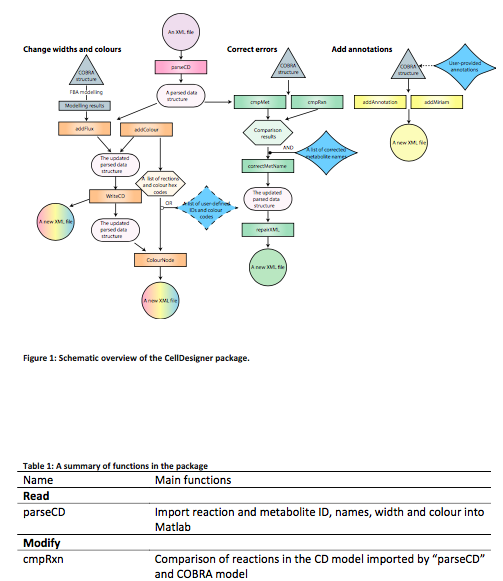

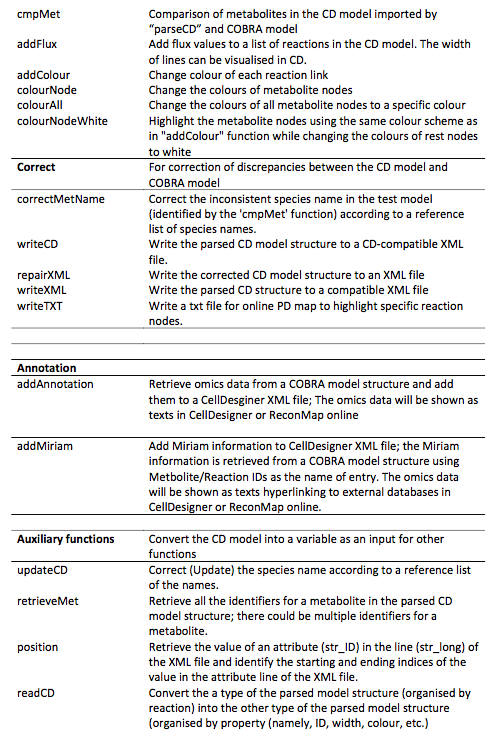

# 3. Parse a CellDesigner file into Matlab

The "parseCD" function read a cellDesigner (CD) file into two types of Matlab variable structures. The first type is suitable to modify the attributes of reactions, such as 'color' and 'width' (these key words are retrieved directly word for word). The second is similar to COBRA model structure and can be used as the inputs for other Matlab functions.

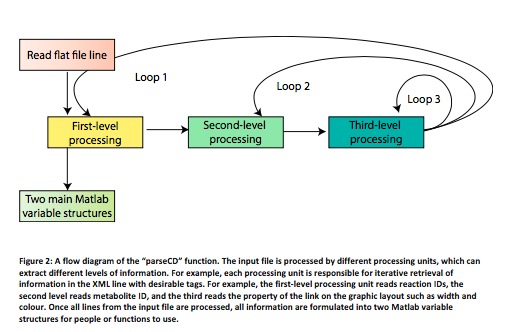

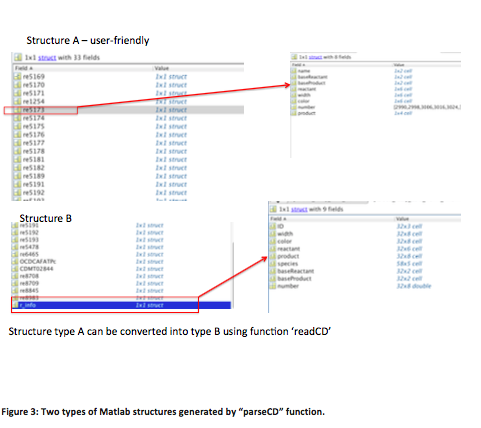

just enter "parseCD" in the command window of Matlab, a file dialogue will pop up asking to choose the XML file that needs to be parsed; alternatively, if the XML file name is known, the file name with single quotation marks can be typed in the parenthesis as follows: 

>> parsed = parseCD('fatty_acid.xml')

% Parse a cellDesigner file into Matlab

% parsed = parseCD('fatty_acid.xml')	

"parsed" is the return variable of the function storing the parsed information of the XML file. 

Whereas the "r_info" is used for algorithms to exchange and process information, the "parsed" form is used for user-end to read. 

Structure A is god user-friendly but takes much longer time to produce. 

Structure B is not good for human to read but is more suitable for other Matlab functions to access the parsed information. 

The following tutorial is intended to provide users a quick to getting started using the useful functions of the package. The tutorial use a network layout of human fatty acid metabolism drawn using CellDesigner beased on Recon 2 - the human metabolic network reconstruction. This tutorial requires the CellDesigner file "fatty_acid.xml". The omics data are extracted from the Matlab file of Recon2 - "recon2.mat". 

# 4. Width and colour attribute modifications

## 4.1 Change the thickness of reaction links

The following command parses the network layout of fatty acid in the CellDesigner format into a Matlab variable. 				

>> parsed= parseCD('fatty_acid.xml') 	

A COBRA function “optimizeCbModel” can be called to obtain a flux distribution for Recon2, where ‘recon2’ is the Matlab variable structure of recon2 (human metabolic reconstruction)  			

>> FBA=optimizeCbModel(recon2) 			

% Parses the network layout in the CellDesigner format into a Matlab variable.

% parsed = parseCD('fatty_acid.xml')

% Call FBA (flux_balance_analysis) to obtain flux distribution for Recon2.

% FBA = optimizeCbModel(recon2)

			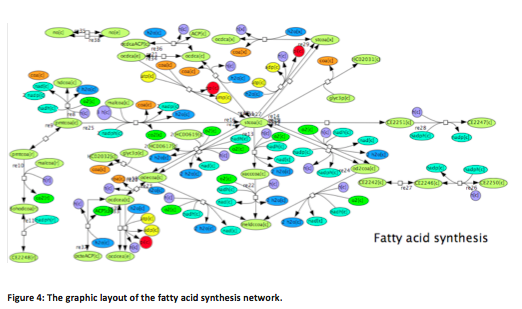

The widths of lines are changed according to flux calculated using FBA using the following commands: 				

1) Change the width of lines. 					

>> [parsed_new, flux] = addFlux(recon2,FBA,parsed,parsed.r_info.ID(1:32,3)) 	

% Change the width of lines.

% [parsed_new,flux] = addFlux(recon2,FBA,parsed,parsed.r_info.ID(1:32,3))

2) Write a new XML file. 					

>> writeCD(parsed_new,'fatty_acid_new.xml') 

% write a new XML file.

% writeCD(parsed_new,'fatty_acid_new.xml')		

A new file, “fatty_acid_new.XML”, can be seen in the current working directory. Open the file with CellDesigner to visualise the network layout. The screenshot of network layout is shown below: 

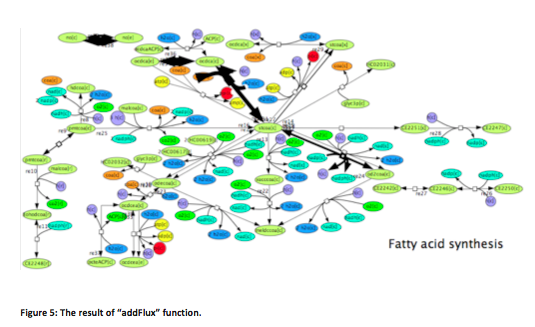				

## 4.2 Change the colour of reaction links 				

Using the following two commands, we can change the colour of reaction links to reflect the flux values (e.g., the higher the flux values, the darker the colours). In the example, the reaction carrying high fluxes are highlighted in red, whereas those with comparatively low fluxes are highlighted in blue. 				

>>[parsed_new] = addColour(parsed_new,(parsed.r_info.ID(1:32,3))) 

%  colour the reactions depending on their flux.
%  high fluxes highlichted in red
%  low fluxes highlighted in blue

% [parsed_new]=addColour(parsed_new,(parsed.r_info.ID(1:32,3)))

% writeCD(parsed_new,'fatty_acid_new.xml')


This command returns an updated parsed data structure, whose the colour attributes are modified for some reactions. 				

The CD file uses a variation of the standard hex colour codes to specify colours. Examples of colour codes can be found at http://www.color-hex.com. The colour is represented by a six- digit code, e.g., ‘#b3c628’, but, for CellDesigner to recognise, it is needed to remove ‘#’ from the code and add ‘ff’ before ‘b3c628’, which converts the six-digit code into an eight-digit code, ‘ffb3c628’. In the tutorial, it is not necessary to include ‘#’ in the colour code when calling package functions. The functions can automatically check if a prefix, ‘#’, exists in the colour code and remove the prefix if it exists. 					

**Note: **					

The second argument may contain two columns. The first column is a list of reaction IDs, while the second is optional containing a list of hex colour codes. When the second column is empty, a default colour scheme will be used for highlighting; on the other hand, when the colour codes are provided in the second column, these provided codes will be used to highlight reactions. 					

There are five predefined sets of colour palettes. Each palette number (1-5) is used as the third agurment for “addColour” function. For example, Red pt1 Color Palette (5) is chosen in the following command. 					

>>[parsed_new] = addColour(parsed_new,(parsed.r_info.ID(1:32,3)), 5) 

% choose a specific set of colour palettes (from a total of 5)
% example with palette number 5

% [parsed_new]=addColour(parsed_new,(parsed.r_info.ID(1:32,3)),5)


	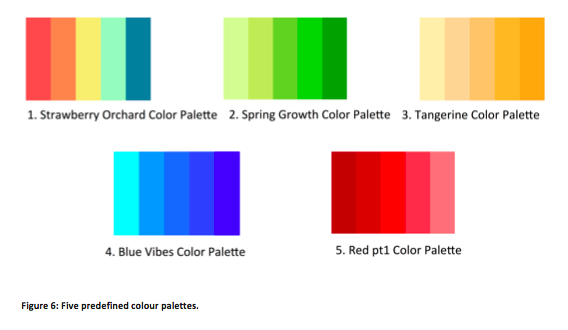	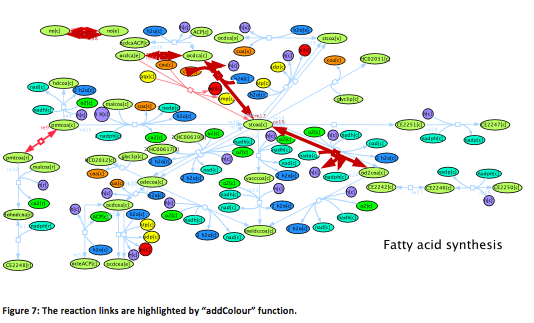			

## 4.3 Export coloured nodes to a text file 				

A simple function ‘writeTXT’ can be called to produce a text file containing a list of reaction IDs and a list of colour hex codes. The text file can be uploaded to ReconMap online to highlight reaction links on ReconMap. This function uses the return variable of “addColour” function as the input. 					

>> writeTXT(list_nodes,'test.txt')

% produce a text file containing a list of reaction IDs and a list of colours hex codes.
% "list_nodes" contains a list of reactions ID and a list of colour codes
% "Test.txt" is a name of the text file

% writeTXT(list_nodes,'test.txt')

“list_nodes” contains a list of the reaction IDs and a list of colour codes; it is one of the output variables of “addColour” function. One of the return variables of the function “addColour”, “listRxn” can be used as the “list_nodes” . 

“text.txt” is a name of the text file. 					

## 4.4 Change the colour of metabolise nodes 

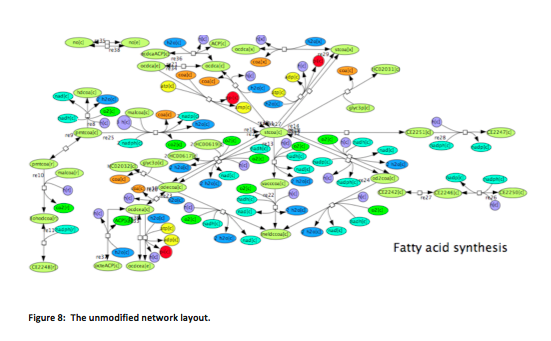					

“colourNode” function can be used to change the colours of metabolite nodes. “list_Met” can be set to “false”, then the function will not highlight metabolite and only reaction nodes, specified in a reaction list, are highlighted. 					

The return variable of the “addColour” can be use as the input for “colourNode”. Then, the same colour of the reaction link will be used to highlight the metabolite nodes involved in a reaction. 

>> [parsed_new,var,final_list]=colourNode(parsed,'fatty_acid_new.xml',parsed.r_info.ID(:,2),'fa lse') 

% Change the colour of metabolite nodes from a list. The same colour of the reaction link will be used to highlicht the metabolite. 

% [parsed_new,var,final_list]=colourNode(parsed,'fatty_acid_new.xml',parsed.r_info.ID(:,2),'false')

 			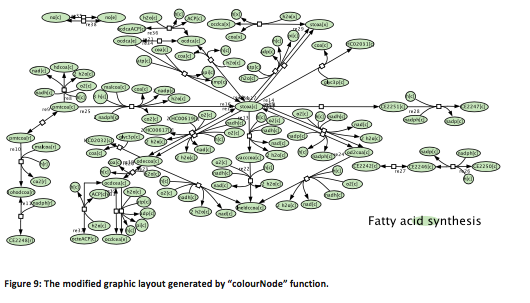

% [parsed_new, flux] = addFlux(recon2,FBA,parsed_new,parsed.r_info.ID(1:32,3))
% [parsed_new] = addColour(parsed_new,(parsed.r_info.ID(1:32,3)),5)
% writeCD(parsed_new,'fatty_acid_new.xml')

>> [parsed_new, flux] = addFlux(recon2,FBA,parsed_new,parsed.r_info.ID(1:32,3))

>> [parsed_new] = addColour(parsed_new,(parsed.r_info.ID(1:32,3)),5)

The value “5” indicates that Red pt1 Color Palette is used to highlight metabolite nodes. 

>> writeCD(parsed_new,'fatty_acid_new.xml') 

				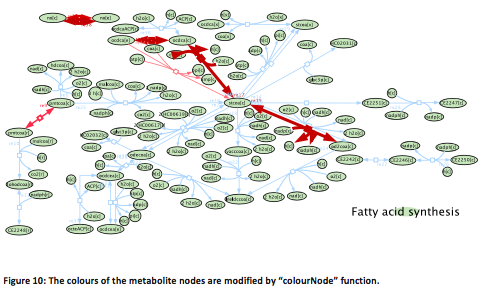				

>>[parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',parsed_new.r_inf o.ID(:,3),'false') 					

parsed_new.r_info.ID(:,3) contains a list of reaction IDs. 					

>>[parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',listRxn,'false') 

% [parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',parsed_new.r_inf o.ID(:,3),'false')
% [parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',listRxn,'false')

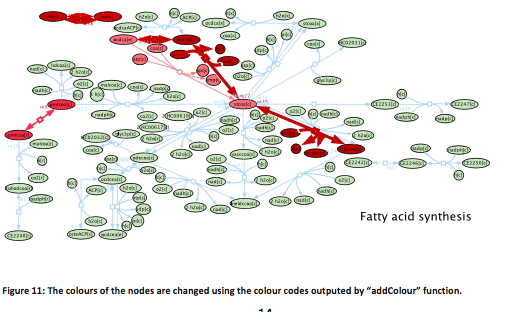

>>[parsed_new,listRxn] = addColour(parsed_new,(parsed.r_info.ID(1:32,3)),5) 		

% [parsed_new,listRxn] = addColour(parsed_new,(parsed.r_info.ID(1:32,3)),5)

Another function” colourNodeWhite” can be called as a shortcut to set all other reactions except those listed in “listRxn” to white, and then set reactions listed in “listRxn” using the same colour scheme passed from “addColour” function. 					

>>[parsed_new,var,final_list]=colourNodeWhite(parsed_new,'fatty_acid_new.xml',listRxn,'fals e') 

% [parsed_new,var,final_list]=colourNodeWhite(parsed_new,'fatty_acid_new.xml',listRxn,'fals e')

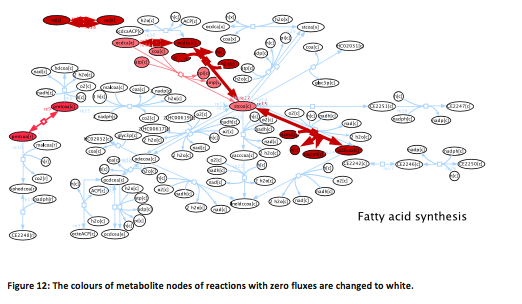		

# 4.5 Change colour of metabolite nodes of reactions 					

>> [parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',listRxn,listMet) 

% Change the colour of metabolites from a ID list. 

% [parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',listRxn,listMet)			

The additional argument “ listMet” contains the metabolite IDs that are needed to be highlighted for two reactions ‘re5161’ and ‘re5168’ of the variable “listRxn”; in other words, ‘pmtcoa[r]’ in reaction ‘re5161’, and ‘nadp[c]’ and ‘nadph[c]’ in reaction ‘re5168’ will be highlighted in orange colour by default. 

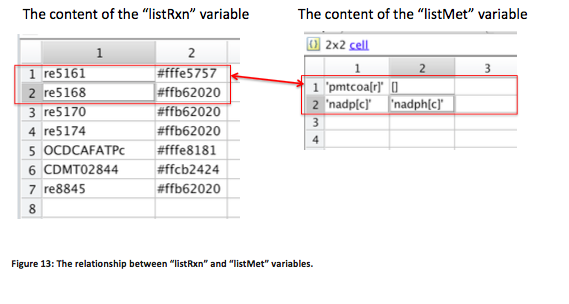	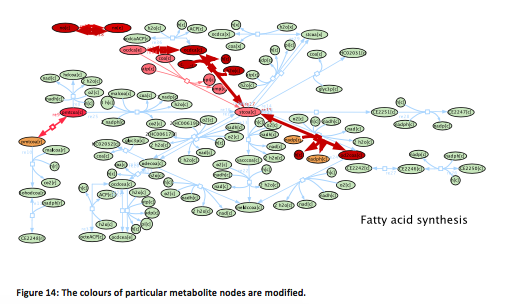				

The default orange for highlighting metabolite nodes can be changed by using the fifth attribute of the function to specify a list of colour codes for the list of metabolite IDs in the “listMet” variable. 					

>> [parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',listRxn,listMet,list MetColour) 

% specify the colour of each metabolite addint the MetColour list (list of colour codes for the list of metabolite IDs in the “listMet”)

% [parsed_new,var,final_list]=colourNode(parsed_new,'fatty_acid_new.xml',listRxn,listMet,list MetColour) 

	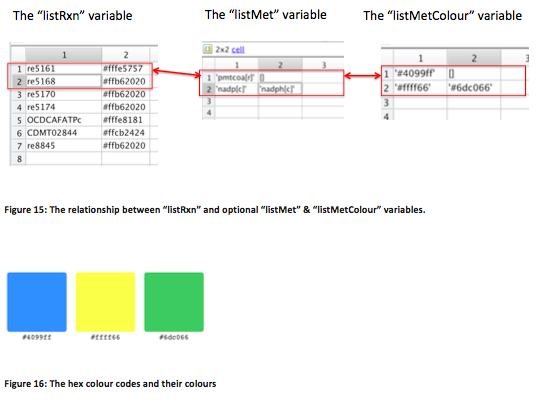		

	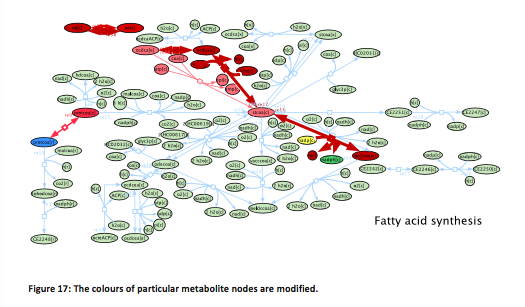				

The row number in “listMet” variable corresponds to the same row number in “listRxn” variable. The “colourNode” function first check if the metabolites indicated in “listMet” appear in the corresponding reactions in “listRxn’. For example, a screenshot of the “listMet” below shows that the first 30 rows are empty and the metabolites in the first 30 reactions in “listRxn” are not particularly highlighted. Each of rows 31 & 32 contain two metabolite IDs; the function first check if reaction 31 contains metabolite “no[c]” and “o2[c]”, and reaction 32 contains the metabolites “h[c]” and “adp[c]” respectively; only those listed metabolite IDs existing in the corresponding reaction will be particularly highlighted on the graphical layout. The default colour is orange, but can be changed to any other colours by specifying the hex colour codes in “list_Colour_Met”, which is an optional argument of the “colourNode” function. 

	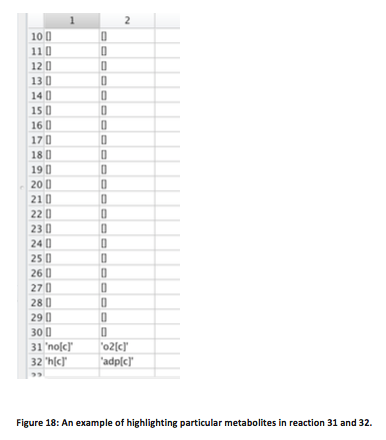

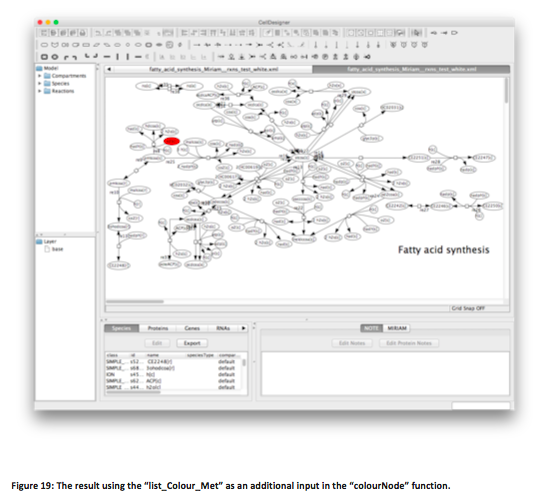				

# 5 Error corrections 		

There could be errors with the species names when the network layout is drawn by human effort. The content (e.g., species names) of a CellDesigner files can be corrected using a COBRA model structure as the reference. The errors in the network layout of ‘fatty acid pathway’ are corrected through the following steps.	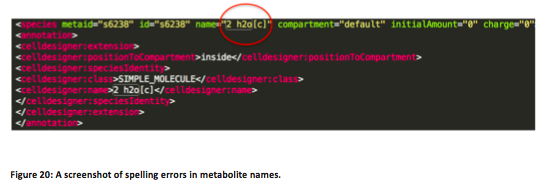

# 5.1 Check and correct species names 				

“cmpMet” and “correctMetName” functions can be used to correct species names in a parsed CD model 				

>> results =cmpMet(parsed_new,model) 

% Correct species name in a parsed CD model 

% results = cmpMet(parsed_new,model) 

				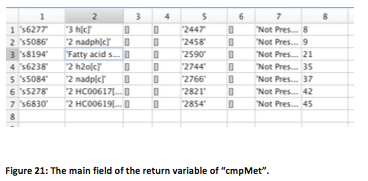					

This command intends to produce a “r_info” structure that is updated with the identified changes to the metabolite names. 				

1. The first argument stores the parsed model structure. The structure is the same as “parsedModel.r_info” 				

2. The second argument is the return variable of the ‘cmpMet’ function. Basically, the second field of the variable contains a list of row numbers of the problematic species names which is used by ‘correct_M’ function to locate the incorrect metabolite names in the array and replace them with the provided substituting species names contained the third argument. 				

The following command corrects the wrong species names with reference to a list of correct species names. 		

% Correct species name in a parsed CD model obtaining a list of wrong and right species names. 

% parsed_corrected=correctMetName(parsed_new, results, list_new_names) 

>> parsed_corrected=correctMetName(parsed_new, results, list_new_names) 				

The following is the screenshot of the list of substitute metabolite names 

		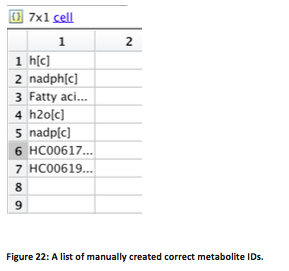					

Optionally, “cmpMet” function can then be called again to check if the there would be any further discrepancies existing between the COBRA and parsed CellDesigner models. 				

>> results=cmpMet(parsed_corrected,model) 

% Re-check if there are discrepancies between the COBRA and the parsed CD model. 

% results=cmpMet(parsed_corrected,model) 

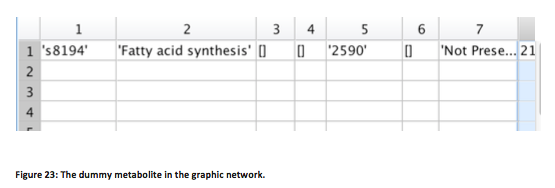				

The result indicates that there is only one metabolite that cannot be found in the reference COBRA model structure. The metabolite name is “Fatty acid synthesis’, which is a dummy metabolite shown on the network layout as a name label of the whole network. Therefore, it is fine to leave where it is. 				

# 5.2 Repair the XML file 				

The following command writes an updated parsed model structure to a new XML file. 				

>> XML = repairXML(parsed_corrected,'fatty_acid_corrected.xml') 			

% updated parsed model structure to a new XML.file

% XML = repairXML(parsed_corrected,'fatty_acid_corrected.xml') 	

This command intends produce a variable “text” that stores all the text lines of the XML file, using “annotedText” as a reference, which is outputted by “writeXML” function. 							

−  “parsed_corrected” is the corrected parsed model structure outputted by “correctMetName” function. 						

−  “fatty_acid_corrected.xml” is the name of the output XML file. 						

−  “XML" contains text lines of the output XML file. 

The following is the screenshot of the corrected network layout, in metabolite IDs with stoichiometric coefficients (such as “3 h[c]”) are changed to metabolite IDs (such as “h[c]”). 

	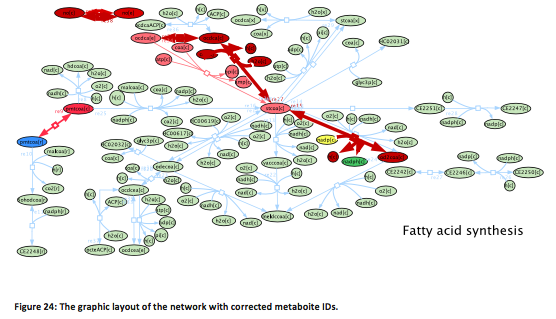				

# 5.3 Check reaction names 				

“cmpRxn” function can be called to check if there are any discrepancies in reactions between the parsed CD and the COBRA models. 				

>>results =cmpRxn(parsed_corrected,model) 

% Check discrepancies between parsed CD and the COBRA models.

% results =cmpRxn(parsed_corrected,model) 

				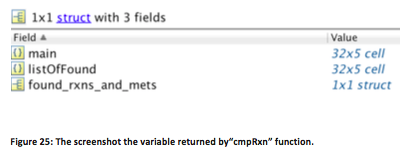			

The result indicates that there is no discrepancy found in reaction identifiers between the CD and COBRA model structures. 					

To demonstrate the discrepancies in reactions can be identified by the ”cmpRxn” function, we use the central metabolic network of Recon2 as an example, and compare it with the fatty acid Matlab model structure. 				

>> parsed_Central=parseCD('CentralMetabolism_Recon2.xml') 			

The following command uses “cmpRxn” function to compare the parsed central metabolism structure (i.e., CD model) with the fatty acid COBRA model structure (i.e., COBRA model). 				

>> results =cmpRxn(parsed_Central,model) 	

% To identify discrepancies between the CD and the COBRA model.

% parsed_Central=parseCD('CentralMetabolism_Recon2.xml') 

% results =cmpRxn(parsed_Central,model) 

The result (see below) indicates that three reactions of the parsed CD model are found in the COBRA model, 214 reactions of the parsed CD model are not present in the COBRA model. 				

“main” displays all the comparison results. The 1-3 columns list the all of the available reaction IDs in the CD model; the fifth column lists the comparison results: a “found” text indicates the reaction ID of the CD model is also present in the COBRA model. 				

“listOfFound” contains the reactions of the CD models that are present in both CD and COBRA models. 				

“found_rxns_and_mets” lists all the substrates and products of the reactions present in both CD and COBRA models; the metabolite IDs are retrieved from the COBRA model. 				

“list_of_rxns_not_present_in_ReferenceModel’”lists the reactions of the CD model that are absent from the COBRA model. 

				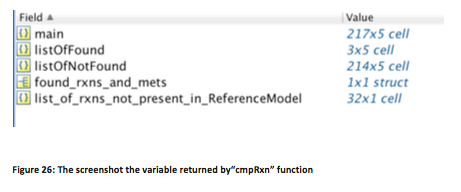				

# 6 Annotation 				

There are two ways to annotate a component (Species or Reaction), by adding free text or MIRIAM notes (the Minimal Information Requested In the Annotation of Models). Free text notes give you flexibilities to add user-defined types of omics data, whereas MIRIAM annotation is a standard scheme to annotate and curate computational models in biology 				

( http://www.ebi.ac.uk/miriam/) and recommended by SBML Level 2 Version 4. 				

## 6.1 Free-text annotation 					

The following command retrieves relevant omics data for reactions from COBRA structure and integrates them with the CD XML file: 				

>> [var]=addAnnotation ('fatty_acid_new.xml','fatty_acid_new_annotated.xml', parsed.r_info.ID(:,3),recon2); 				

% To retrieve relevant omics data form COBRA structure and integrate the with the CD XML file. 

% [var]=addAnnotation ('fatty_acid_new.xml','fatty_acid_new_annotated.xml', parsed.r_info.ID(:,3),recon2);

parsed.r_info.species(:,3) is the list of species names.

The function returns an array of text lines of the XML file, as saved in “var”. 			

The following screenshot shows the added annotations for reaction “OCDCAFATPc” when clicking on the reaction node of the graphical layout in CellDesigner. 

		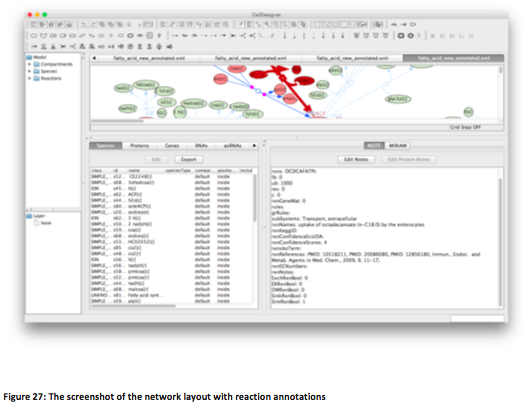					

Then, the omics data for metabolite can be added using the following command: 					

>> [var]=addAnnotation ('fatty_acid_new.xml','fatty_acid_new_annotated.xml', parsed.r_info.species(:,2),recon2); 			

The following screenshot shows the annotations for reaction “coa[c]” when clicking on the metabolite node on the graphical layout in CellDesigner. 

	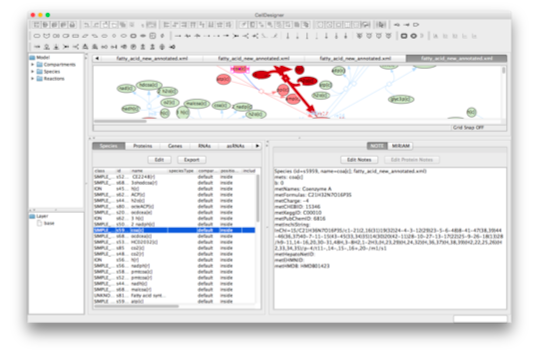		

Instead of calling “addAnnotation” function twice, it is also possible to add omics data for reactions and metabolites using one single command: 			

First, run the following command to combine the lists of reactions and metabolites. 					

>> sumList={parsed.r_info.ID{:,3},parsed.r_info.species{:,2}}' 	

Second, use “sumList” as the third argument of the function, which contains a combined list of reactions and metabolites. 				

>> [var]=addAnnotation ('fatty_acid_new.xml','fatty_acid_new_annotated.xml',sumList,recon2); 			

% Add omics data for reactions and metabolites using one single command. First, combine the lists of reactions and metabolites

% sumList={parsed.r_info.ID{:,3},parsed.r_info.species{:,2}}

% [var]=addAnnotation ('fatty_acid_new.xml','fatty_acid_new_annotated.xml',sumList,recon2);

# 6.2 MIRIAM information 				

The MIRIAM annotations for both metabolite and reactions can be added to the XML file using the following command: 				

>> addMiriam('fatty_acid_new.xml','fatty_acid_miriam.xml',sumList,model_miriam,'name', list(1:15,:)) 					

'fatty_acid_new.xml' - A CD compliable XML file without annotations 'fatty_acid_miriam.xml’ – a new file that contains annotations. 				

sumList - a mixed list of reaction metabolite names, which is produced by merging the lists of metabolite and reactions into one list using the command: 				

>> sumList={parsed.r_info.ID{:,3},parsed.r_info.species{:,2}}'

% Add MIRIAM annotations for metabolites and reactions to the XML file.  First, combine the lists of reactions and metabolites. 

% sumList={parsed.r_info.ID{:,3},parsed.r_info.species{:,2}}'

% addMiriam('fatty_acid_new.xml','fatty_acid_miriam.xml',sumList,model_miriam,'name', list(1:15,:)) 	

model_miriam – A COBRA model structure that contains the necessary MIRIAM annotations. 				

A snapshot of an example structure array is as follows: 

	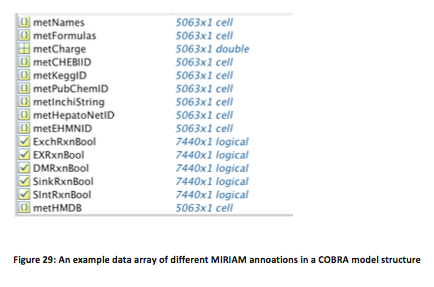				

List - the first column contains a list of field names of data arrays in a COBRA Matlab structure, and each data array contains one type of MIRIAM information; the second column listed the MIRIAM data types for each data array. The third column lists the relations for each type of MIRIAM data. If the third column is missing, the function will generate a list of random relations for the data arrays. 				

For example, ID is a list of reaction IDs, so ’model_t_list2’ should contain the MIRIAM information for a reaction. 				

The screenshot shows the MIRIAM information is added to the XML file. 

			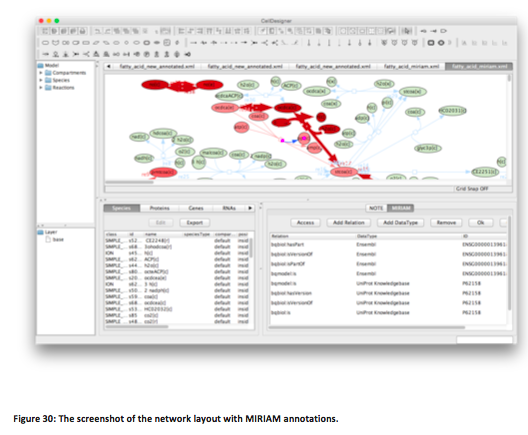				

**NOTE: **				

It should be noted that the ‘XML file’ is the one that is used to produce the ‘parsed model structure’; otherwise there will be errors. 				

Potential errors may be caused by the fact that there is no corresponding fields referring to annotations in the Matlab structure, or the length of the annotation arrays are not consistent with that of the list of reactions or metabolites in the model structure. 					

## 6.3 Other annotation types 				

You can create any omics data using many COBRA functions. For example, it is possible to use COBRA functions to generate different types of annotations, which can then be added to the XML file as free-text annotations. 				

Use COBRA function “printRxnFormula” to create a new field of array of reaction formulas 				

>> model_updated.rxnformulas=printRxnFormula(model,model.rxns(:)) 				

Add all of the annotations to XML file. 				

>> addAnnotation('fatty_acid.xml','fatty_acid_annotated.xml',parsed.r_info.species(1:58,2),mo del_updated); 

% Use COBRA fucntions to generate different types of annotations which can be added to the XML file as a free-text annotations. 

% model_updated.rxnformulas=printRxnFormula(model,model.rxns(:)) 

% addAnnotation('fatty_acid.xml','fatty_acid_annotated.xml',parsed.r_info.species(1:58,2),mo del_updated); 

Unexpected MATLAB expression.